# Projectile Path Quiver Plot

This example shows how to display the path of a projectile as a function of time using a three-dimensional quiver plot. 

The coordinate functions are


$$x(t)=x_0+v_{x0}t+\frac{a_{x0}t^2}{2}+...$$



$$y(t)=y_0+v_{y0}t+\frac{a_{x0}t^2}{2}+...$$



$$z(t) = z_0+v_{z0}t + \frac{a_{z0}t^2}{2}+...$$


You can try playing with the initial conditions. Then add terms for uniform jerk (acceleration proportional to time) of the form $...\rightarrow \frac{j_{x0}t^3}{3!}$.

x0=0;   y0=0;   z0=0;
vx0=2;  vy0=3;  vz0 = 10; % initial conditions (SI units)        
ax=0;   ay=0;   az=-9.81;% acceleration components

dt=0.1;% time interval
t = 0:dt:1;% sequence of times

Calculate the position over time.

x = x0+vx0*t+ 1/2*ax*t.^2;
y = y0+vy0*t+ 1/2*ay*t.^2;
z = z0+vz0*t + 1/2*az*t.^2;

Compute the components of the velocity vectors and display the vectors using a 3-D quiver plot. Change the viewpoint of the axes to `[70,18]`. The `gradient` function simply computes the set of differences between components of the vector, e.g. `gradient(x)=[x(2)-x(1),x(3)-x(2),...]`. So the displacements `u,v,w `below are approximately the components of the velocity vector times the time interval `dt` .

u = gradient(x);
v = gradient(y);
w = gradient(z);
scale = 0;

figure
quiver3(x,y,z,u,v,w,scale)
view([70,18])
xlabel('x (m)');ylabel('y (m)');zlabel('z (m)');

Uncomment the following to project the velocity vector onto the coordinate planes, then tear off the figure (click arrow at top right corner of figure when it is inline in MATLAB) and twirl it in 3d (use the rotate tool at the top of the torn off figure). View from appropriate angles to see the projections.

To uncomment, select the code to uncomment by dragging over it and use the uncomment button to the right of the **Code **button at the top of the Live Script editor. To add a line of code, click at the end of some code and enter a carriage return. To delete a line, select it and hit delete. To add text, click some text and just type, or click at the end of some code, hit carriage return, then click the **Text** button in the Live Script Editor to switch to text. To change text fonts, drag over some text and use the font tools to the right of the Text button. Try it!

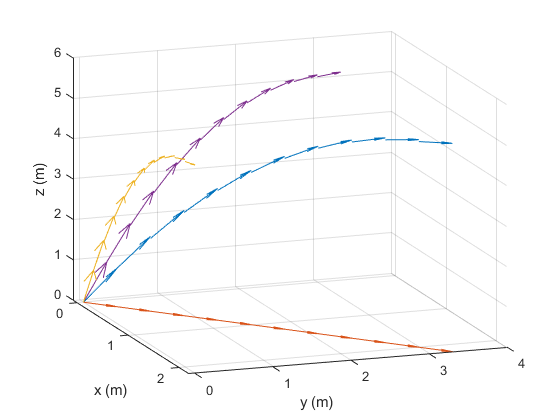

hold on
temp=zeros(1,length(x));
quiver3(x,y,temp,u,v,temp,scale)
quiver3(x,temp,z,u,temp,w,scale)
quiver3(temp,y,z,temp,v,w,scale)

Now change the length of time, initial position, initial velocity, magnitude and direction of the acceleration, then try adding a jerk term.